Vezmeme si BGD s adaptivním moomentem a doděláme to něj způsob, jak najít ideální bázové funkce pro regresi. Použijeme k tomu velkou bázovou funkci s celou řadou různých funkcí (dělčky, násobičky, síny, cosíny atd..), kde všude bude jiný parametr. Poté tzv. Lasso Regression potlačí parametry, které jsou malé (a nejsou tudíž úplně potřeba). To znamená že výpočtem získáme model jen s omezeným počtem parametrů bázových funkcí (rychlejší na výpočet) ale s dobrým proložením. 

Testovací data budou v podobě zašuměnné:

#### 
$$y\left(x\right)=\sin \left(3x+2\right)$$
 

Bázová funkce našeho modelu vzniká podle slovníku:

#### 
$$\begin{array}{l}
u_1 \;=w\;\textrm{id}\left(x\right)+b\\
u_2 =w\;\sin \left(x\right)+b
\end{array}$$


Takže celková bázová funkce bude vypdapat takto:

#### 
$$y\;=\left(w_3 \left(w_1 *x+b_1 \right)+b_3 \right)+\left(w_4 *\sin \left(w_1 *x+b_1 \right)+b_4 \right)+\left(w_5 \left(w_2 *\sin \left(x\right)+b_2 \right)+b_5 \right)+\left(w_6 *\sin \left(w_2 *\sin \left(x\right)+b_2 \right)+b_6 \right)$$


func = @(x) (sin(3.*x+2));            % funkce pro nagenerování dat
from = 0;                           % rozsah pro od ...
to = 2;                             % ... do pro nagenerování dat
N =  200;                           % počet vzorků
x = from:((to-from)/(N-1)):to;      % vzorkovací čas
% y = awgn(func(x),27);               % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)
y = [0.995739142591912,0.908029693242877,0.962037852609747,0.952535492511895,0.824917059988478,0.783301293026892,0.857920149651234,0.765532935544910,0.776547404734430,0.738965158362146,0.749202975593929,0.750883238130212,0.734938540302383,0.687428953596691,0.616698368264148,0.598190472771084,0.625526005887278,0.490791423315628,0.511256471484117,0.468620671250012,0.498266604739401,0.508477703000161,0.565878886339097,0.433092371633456,0.358220564409092,0.357915456740938,0.370563493732015,0.367342249790237,0.272502015784143,0.263845978077634,0.287826126249632,0.215439953818860,0.179440371049058,0.131304796984824,0.0990231899002019,0.133468411636997,0.0323876352556879,0.0239003349723465,-0.0503149915777220,-0.00731170900465960,-0.0532626247696962,-0.0747242329097607,-0.125618519367122,-0.187419492774914,-0.187797233859656,-0.270893329612027,-0.258012632444160,-0.168962781544416,-0.226207455338311,-0.290757081382095,-0.338264298220104,-0.348898495041766,-0.396057749151022,-0.399097269483036,-0.413717864272771,-0.539630501964308,-0.528529993978957,-0.546725130684208,-0.595326265083096,-0.639437620094427,-0.562163719772415,-0.612552635411554,-0.705877222729557,-0.734422682685863,-0.689901073406638,-0.760690260680002,-0.803721162635902,-0.780840836151143,-0.826412621632040,-0.768904289987861,-0.721266588119365,-0.916969016443331,-0.819508744502019,-0.853198690179134,-0.924060354215107,-0.857020064394276,-0.952390876433628,-1.00868887904588,-0.985851244276608,-0.920061270214945,-0.936911421718321,-0.918936473655348,-0.949409488969060,-0.921758700869446,-1.07344448580434,-1.00243625723618,-1.00910111858280,-0.998603376735115,-0.950583432871879,-1.02979510483659,-0.988722619257929,-1.08485563624788,-1.03899816916788,-0.953810073479699,-1.07047142365058,-0.925281581400207,-1.00509262440268,-0.953988247888581,-1.02331072965515,-0.929375398494350,-0.954602165330373,-0.889102321947617,-0.959262262763164,-0.956558327895111,-0.945515468150404,-0.810738480288209,-0.900058664284140,-0.942783767097736,-0.813330012161948,-0.838597685716578,-0.838856520836561,-0.782374852953575,-0.747585778399898,-0.796741942519833,-0.743680445088718,-0.742183825902448,-0.733141452804232,-0.664446108679425,-0.631209787745264,-0.701775839859894,-0.567546197377226,-0.586484082292484,-0.579135416874556,-0.614489669032494,-0.529472715938986,-0.495068414960477,-0.460855381217383,-0.458097192180685,-0.369941059623825,-0.313601865364468,-0.300078419768939,-0.337590500801295,-0.283666787532407,-0.251584024665139,-0.268375074811030,-0.211743472739149,-0.208010136041426,-0.148870061761907,-0.0501583134331642,-0.100454348041448,-0.0946818244824139,0.0296043168957016,0.0372202536477535,0.00489984553951529,0.0255693499823464,0.151580202675217,0.119946584230668,0.156700078706022,0.193771722100025,0.179653747640208,0.285785365045187,0.371435952029693,0.184134517086533,0.332772316672045,0.394530766250012,0.344807601825081,0.412072216212787,0.443020551254939,0.435551381614695,0.520423037837231,0.569203334666957,0.550517204160000,0.582175034282929,0.565854064985518,0.664292479593585,0.633806719195608,0.680450158030686,0.735568567618768,0.691522873471433,0.717191793969063,0.750316426347194,0.756023640703599,0.728348907775451,0.824895568706979,0.756543673161648,0.824176231441024,0.790944608030181,0.927292031194779,0.887485997646068,0.918775809262178,0.898535555502198,0.993224454200940,0.915526147518080,0.995395870288871,1.00498117610812,0.938650574578286,0.989087302665050,0.982462421391660,1.07729146027605,0.943525739181018,0.921376231954271,1.00935826337843,0.954575029083723,0.973075214005514,1.01479337303000,0.941695144153505,1.04632779110546,1.01515210137752,1.05683152289087,0.975428374878585];

Koeficient $\alpha$ je klasicky koeficient učení a koeficient $\tau$ zase maximální přípustnou chybu v modelu.

alpha = 100e-3;   % míra učení 
tau = 3*1e-1;     % maximální možná chyba pro ukončení výpočtu

Koeficient $\lambda$ zase vyjadřuje, jak moc budou malé koeficienty tlumené. Pokud bude $\lambda$ hodně velké, tak utlumí všechny koeficienty a aproximace bude velmi špatná. Pokud bude naopak příliš malé, tak se v řešeení nijak neprojeví. Pokud ale nastavíme tento koeficient na rozumnou hodnotu, tak můžeme docílit stále kvalitně aproximujícího modelu, který ale bude mít určité koeficienty téměř nulové. To znamená, že je můžeme z modelu vypusitit a tím zrychlit následný výpočet.

lambda = 1e-3; % koeficient regularizace pro malé koeficienty.

Naše bázová funkce má tedy podobu podle slovníku výše. Následující kód generuje právě tuto funkci vytvoří:

dictionary_size = 2;
number_of_layer = 2;
syms x_sym
syms sym_w
syms sym_b
syms y_n_sym [dictionary_size,1]

y_n_sym(1) = sym(sym_w * x_sym + sym_b);
y_n_sym(2) = sym(sym_w * sin(x_sym) + sym_b);

number_of_coefficients = (dictionary_size) + (number_of_layer-1)*dictionary_size^(2);

syms w_sym [1,number_of_coefficients+dictionary_size];
syms b_sym [1,number_of_coefficients]; 

y_sym = sym(0);

for i = 1:dictionary_size
    for j = 1:dictionary_size

        a = subs(y_n_sym(i),sym_w,w_sym(i));
        a = subs(a,sym_b,b_sym(i));
        b = subs(y_n_sym(j),sym_w,w_sym(j+(dictionary_size*i)));
        b = subs(b,sym_b,b_sym(j+(dictionary_size*i)));
        c = subs((sym_w * x_sym),sym_w,w_sym(number_of_coefficients+dictionary_size-(dictionary_size-j)));
        
        z = subs(b,x_sym,a); 
        z = subs(c,x_sym,z); 
        
        
        y_sym = y_sym + z;
        
    end
end

Aby byl vliv Lasso regularizace patrný, tak vypočteme jeden a ten samý příklad několikrát pro různé hodnoty regularizace a porovnáme je mezi sebou. Z toho důvodu si předpřipravíme vše co je možné, aby následný výpočet trval co nejkratší dobu. Takže zde je připraven výpočet pro ztrátovou funkci a koeficienty pro výpočet adaptivního momentu.

model = subs(y_sym,x_sym,x);
epsilon = 10e-8;
beta1 = 0.9;
beta2 = 0.999;

Tato proměná počítá kolikrát byl výpočet pro různé hodnoty regularizace proveden.

counter = 1;

Tato proměná zase vypovídá o tom, jaké hodnoty regularizace budou počítány

% range = -3:0.05:1;

A nyní už výpočet. Ten začíná výjádřením ztrátové funkce podle vzorce metody nejmenších čtverců s Lasso regularizací:

#### 
$$E=\left(\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -y_{\textrm{aproximovaé}} \right)}^2 \right)+\lambda \left(|w_1 |+|w_2 |+|w_3 |+\ldotp \ldotp \ldotp +|w_m |\right)$$


kde vzorec metody nejmenších čtverců je klasický, ale je zde připočítávána absolutní hodnota všech koeficientů přenásobená koeficientem $\lambda$.  Následuje už pouze výpočet gradientu, nastavení počátečních koeficientů a samotný výpočet za pomocí ADAMa.

% for j = range
%    
%     lambda = (0.1^-j); %     lambda = (0.1^-0.5);
%     lasso = lambda.*(sum(abs([w_sym b_sym])));
%     E_sym = sum(((y-model).^2) + lasso); %     E_sym = sum(((y-model).^2));
%     
%     grad_E_sym = gradient(E_sym,[w_sym,b_sym]);
%     
%     m = 0;
%     v = 0;
% 
%     w = [2;0.3;-0.2;0.5;1;0.7;0.1;1.2];  % w = (4.*rand(number_of_coefficients,1)-2); % náhodné koeficienty v rozmezí -2 až 2... %     w = (ones(number_of_coefficients,1));
%     b = [1.5;0;0.2;0.1;-0.5;0.2];
%     
%     koef = [w;b];
%     iter = 300;
%     
%     for i = 1:iter 
%    
%         grad_E = double(subs(grad_E_sym,[w_sym b_sym],koef'));
%         
%         m = beta1.*m+(1-beta1).*grad_E;
%         v = beta2.*v+(1-beta2).*grad_E.^2;
%  
%         mm = m./(1-beta1^i);
%         vv = v./(1-beta2^i);
%        
%         if (abs(max(grad_E)) < tau)
%             iter = i;
%             break;
%         end
% 
%         koef = koef - ((alpha.*mm)./(sqrt(vv)+epsilon));
%             
% %         w = koef(1:8)
% %         b = koef(9:14)
% % %         y_model = double(subs(subs(y_sym,w_sym,w'),x_sym,x));
% %         y_model = double(subs(subs(y_sym,[w_sym b_sym],koef'),x_sym,x));        
% %         plot(x,y_model);
% %         drawnow;
%     
%     end

Po nalezení koeficietů jsou koeficienty vypsány, a uloženy do matice pro pozdější vykreslení. 

%     w = koef(1:8)
%     b = koef(9:14)
%     iter
%     KOEF(:,counter) = koef;


Zde jsou vpočteny body podle aproximace, a to z důvodu, abychom mohli vypočíst pomocí metody nejměnších čtverců jejich odchylku od naměřených dat. Tyto odchylky ukládám do matice mse (mean square error) pro pozdější vykreslení.

Následuje vykreslení naměřených dat.

plot(x,y,"ro");
hold on;

for i = range
    
    koef = KOEF(:,counter);
    
    y_model = double(subs(subs(y_sym,[w_sym b_sym],koef'),x_sym,x)); 
    mse(counter) = Least_squares_method(y,y_model);

Vykreslení aproximace vypočteným modelem.

    plot(x,y_model);
    hold on;

Je inkrementován čítač a výpočet běží pro další hodnotu $\lambda$.

    counter = counter + 1; 
end

Vypočtené výsledky můžeme zobrazit takto: 

První gaf ukazuje, že čím větší Lasso regulatizaci jsme zavedli, tím víc nám utlumovala i koeficienty (v našem případě jen koeficient $w_4$), které utlumeny být neměly. V důsledku toho je pro velkou regularizaci model výrazně hoorší. Naoopak pro malé hodnoty $\lambda$ je vidět, že nám výslednou hodnotu ztrátové funkce spočtenou metodou nejmenších čtverců už prakticky nemění. 

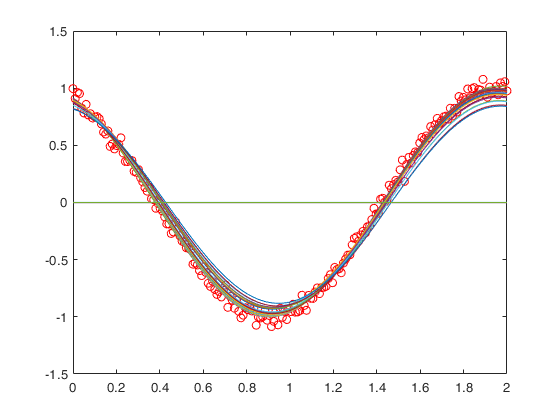

hold off;

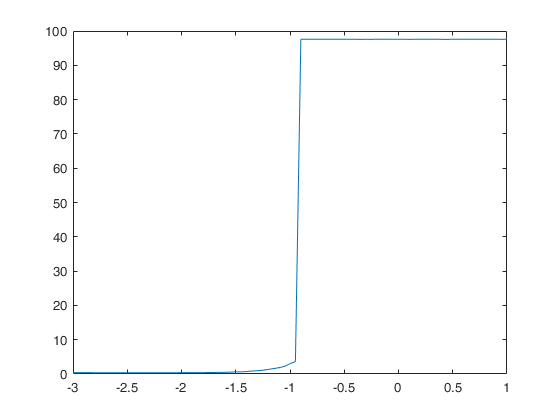

plot(range,mse);
hold off;

Druhý graf zobrazuje jakou měli koeficienty hodnotu napříč všemi výpočty. Lze vidět, že pro malé hodnoty $\lambda$ byli všechny koeficienty nenulové, ale ty nejmenší byli následně tlumeny až do zanedbatelné velikosti. Zároveň je ale vidět, že pro velké $\lambda$ nám regularizace utlumila všechny koeficienty, čili i koeficient $w_4$, který byl pro aproximaci stěžejní. 

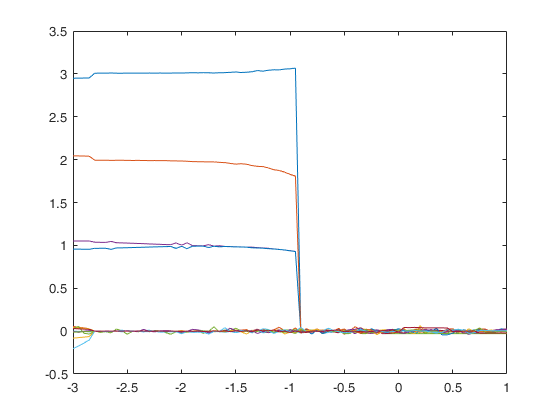

for i = 1:number_of_coefficients*2+dictionary_size
    plot(range,KOEF(i,:));
    hold on
end
hold off

Nakonec si vykreslíme Paretovo optimum závislosti počtu nenulových koeficientů v modelu ku hodnotě nejmenších čtverců. Pro tento účel vytvoříme vektor noc (number of coefficients), který naplníme podle toho, kolik koeficientů bylo při dané hodnotě lasso regularizace nenulových. Hodnota nejmenších čtverců odpovídá hodnotám grafu výše. Barvou je vyjádřena hodnota koeficientu $\lambda$.

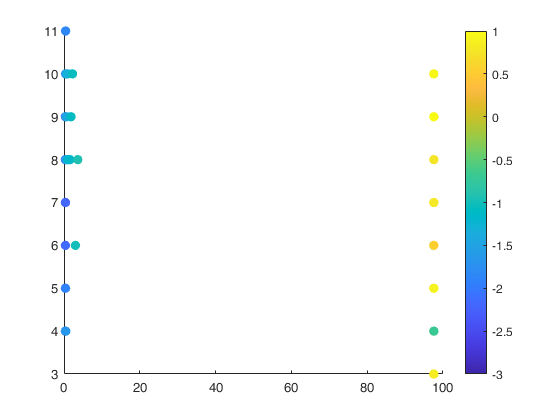

noc = zeros(1,(counter-1));
for i = 1:counter-1
    for j = 1:number_of_coefficients*2+dictionary_size
        if (KOEF(j,i)>0.0007) % 0.0007 je můj určený trashold pro nulový koeficiet v tomto případě
            noc(i) = noc(i) + 1; 
        end
    end    
end
scatter(mse,noc,50,range,'filled')
colorbar